- Use least squares regression to fit a straight line to the following data (implement the formula from the lectures in Matlab).

q1;

    0.3591    4.8881



2. Calculate the correlation coefficient for the best fit line from question 1.

q2;

Correlation Coefficient (r): 0.94493


4. The following data were gathered to determine the relationship between pressure and temperature of a fixed volume of 1 kg of nitrogen (molar mass of 14.006747 g/mol). The volume is 10m^3. Use the ideal gas law equation to determine the universal gas constant, R.

 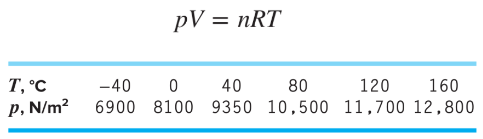

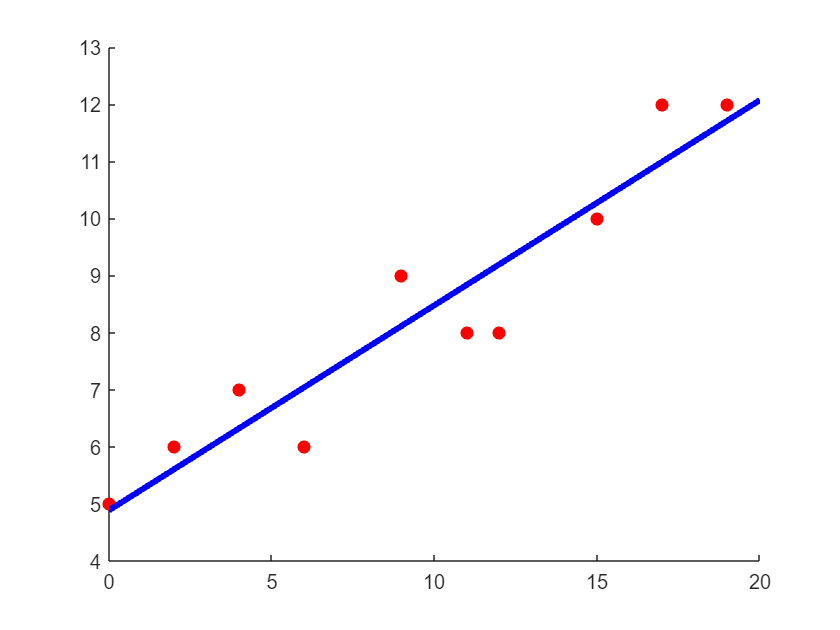

   1.0e+03 *

    0.0296    8.1152

    8.2940



q4;

5. Linearise the following model and use it to estimate the parameters α4 and β4 for the following data. Plot the data with the line of best fit and calculate the correlation coefficient.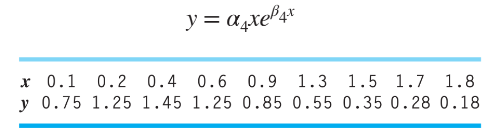

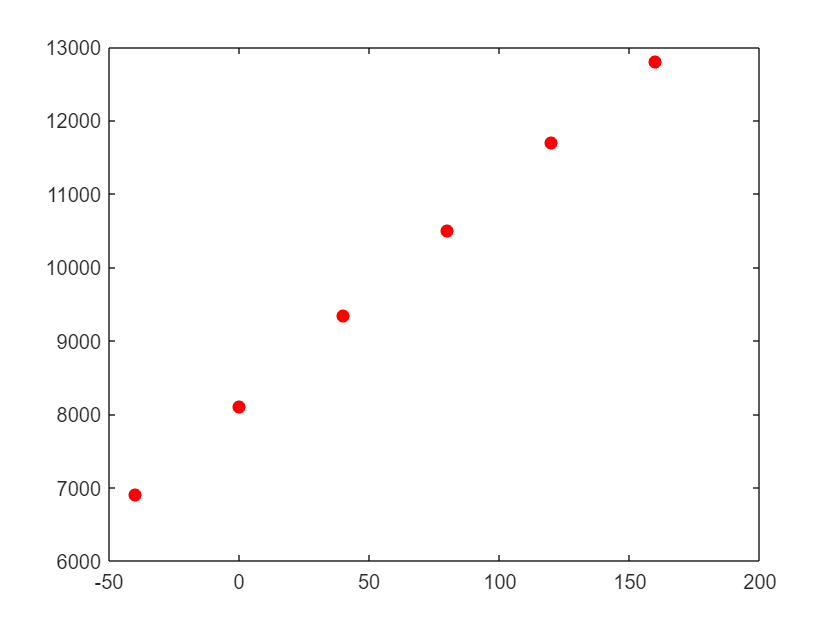

The fitting equation is:
y = 9.661786 x*exp(-2.473309 x)
The correlation of coefficient is: -0.845973


q5;

6. Try fitting a power equation to the following data on metabolisms of animals then using it to predict the metabolism rate of a 200kg tiger.

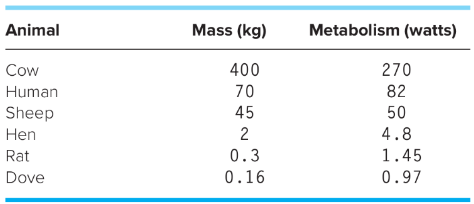

q6;

Tiger metabolism :
  159.2047



7. The following data represents bacteria growth. Two models have been proposed for this growth.

Where k is the growth rate and c is the concentration. Fit the data below to both of these models by transforming them into linear relationships and finding the parameters *k**m* and *c**s*. Which model fits the data better? Predict the growth of bacteria when c = 2 mg/L.

%q7;

8. A transportation engineering study was conducted to determine the proper design of bike lanes. Data were gathered on bike lane widths and average distance between bikes and passing cars. The data from 9 streets are:

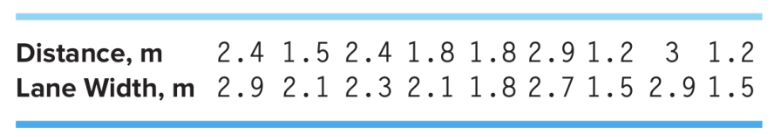

(a) Plot the data.

(b) Fit a straight line to the data with linear regression. Add this line to the plot. 

(c) If the minimum safe average distance between bikes and passing cars is considered to be 1.8m, determine the corresponding minimum lane width.

q8;

Lanewidth of 1.8 distance in m:
    2.0370



9. The table below shows the 2015 world record times and holders for outdoor running. **Fit a power model **for each gender and use it to predict the record time for a half marathon (21,097.5m). Note: the actual records for the half marathon are 3503s (Tadese) and 3909s (Kiplagat) for men and women, respectively.

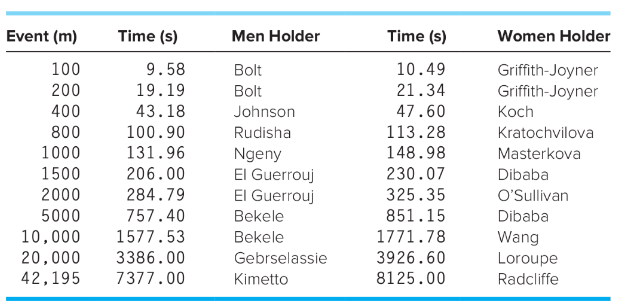

TM = [9.58, 19.19, 43.18, 100.90, 131.96, 206, 284.79, 757.4, 1577.53, 3386, 7377]

TM = 1.0e+03 *

    0.0096    0.0192    0.0432    0.1009    0.1320    0.2060    0.2848    0.7574    1.5775    3.3860    7.3770


TW = [10.49, 21.34, 47.6, 113.28, 148.98, 230.07, 325.35, 851.15, 1771.78, 3926.6, 8125]

TW = 1.0e+03 *

    0.0105    0.0213    0.0476    0.1133    0.1490    0.2301    0.3254    0.8511    1.7718    3.9266    8.1250


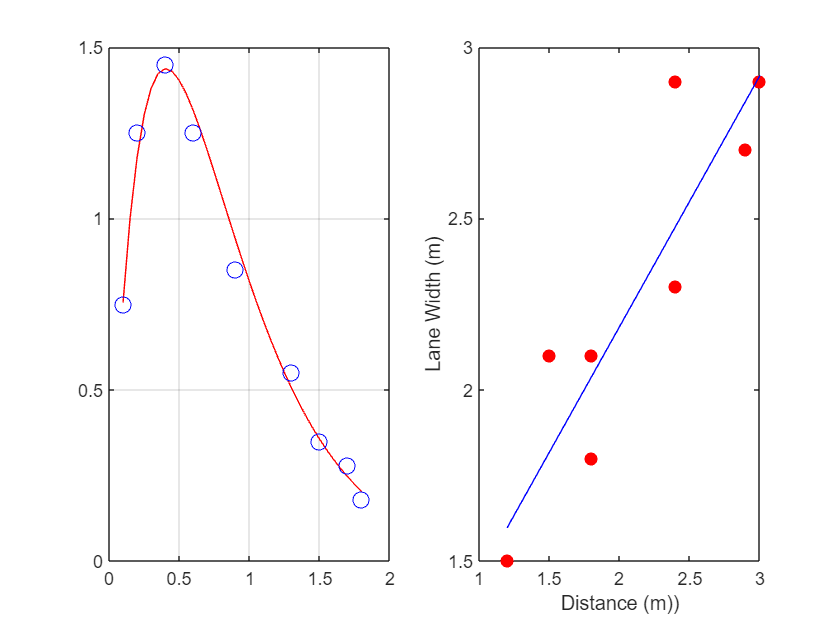

   1.0e+03 *

    0.0108    0.0233    0.0503    0.1086    0.1392    0.2184    0.3007    0.8325    1.7988    3.8866    8.9115

Half Marathon Time (s):
   4.1244e+03



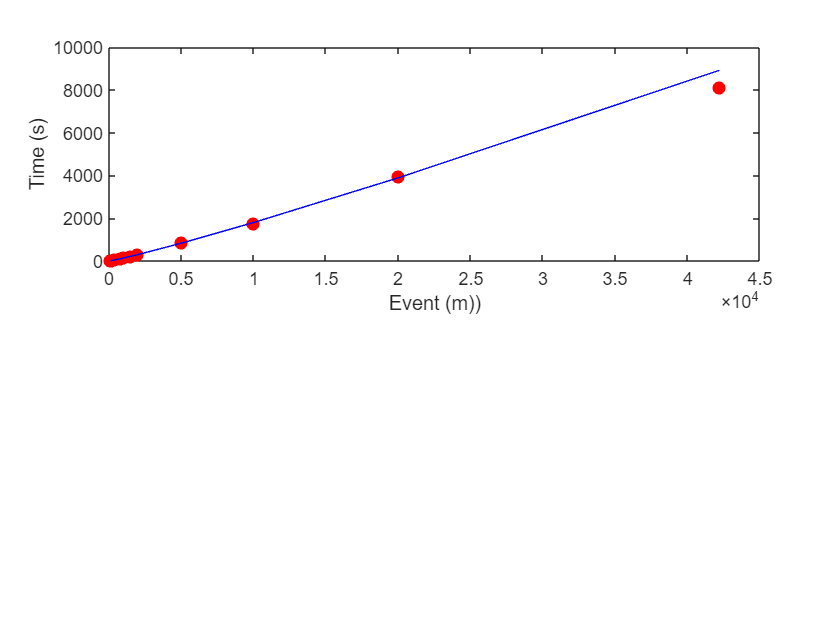

q9(TW);

--------------------------------------------------------------------------------------------------------------------------------------------------

function q1()
    x = [0, 2, 4, 6, 9, 11, 12, 15, 17, 19];
    y = [5, 6, 7, 6, 9, 8, 8, 10, 12, 12];
    a = polyfit(x, y, 1);   %find m and c in y = mx + c
    disp(a)
    hold on
    plot(x, y, 'or', MarkerFaceColor='r')
    x = linspace(0, 20);
    y = polyval(a,x);   %polyval = polyvalue from a and x
    plot(x,y,'b','Linewidth',3)
    hold off
end


function q2()
    x = [0, 2, 4, 6, 9, 11, 12, 15, 17, 19];
    y = [5, 6, 7, 6, 9, 8, 8, 10, 12, 12];

    % Calculate the correlation coefficient
    correlation_matrix = corrcoef(x, y);
    correlation_coefficient = correlation_matrix(1, 2);
    
    disp(['Correlation Coefficient (r): ', num2str(correlation_coefficient)]);
end


function q4()
    hold off
    % Given data
    P = [-40, 0, 40, 80, 120, 160]; % Replace with your actual pressure data in Pa
    T = [6900, 8100, 9350, 10500, 11700, 12800]; % Replace with your actual temperature data in K
    
    % Constants
    V = 10; % Volume in m^3
    mass = 1; % 1 kg
    molar_mass_N2 = 14.006747 * 2; % g/mol

    % Calculate the number of moles (n)
    n = mass * 1000 / molar_mass_N2; % Convert mass to grams and use molar mass in g/mol

    a = polyfit(P, T, 1);
    disp(a)

    syms R
    findR = n * R / V == a(1);
    solR = solve(findR, R);
    disp(double(solR))
    
    plot(P, T, 'or', MarkerFaceColor='r')
end


function q5()
    hold off
    % Note: y = alpha*x*exp(beta*x)
    % Step 1: Define our domain
    x = [0.1 0.2 0.4 0.6 0.9 1.3 1.5 1.7 1.8];
    y = [0.75 1.25 1.45 1.25 0.85 0.55 0.35 0.28 0.18];
    
    % Step 2: Linearized our function
    func = log(y./x);
    a = polyfit(x, func, 1);
    Y = polyval(a, x);
    
    % Note: y = a * x(e^bx)
    % Linearized form: ln(y) = ln(alpha) + beta * x
    % Therefore: a(2) = ln(alpha) | Intercept, and a(1) = beta | Slope
    alpha = a(2);
    beta = a(1);
    alpha4 = exp(alpha);
    
    % Step 3: Plot graph
    subplot(1,2,1);
    title('Actual Function');
    func_y = @(x) alpha4 .* x .* exp(beta .* x);
    X = 0.1:0.05:1.8;
    
    plot(X, func_y(X), 'r');
    hold on
    grid on
    plot(x, y, 'bo', 'MarkerSize', 8);
    
    subplot(1, 2, 2);
    title('Linearized Function');
    plot(x, Y, 'b.');  % Linearized function
    hold on
    grid on
    plot(x, func, 'r-.');
    
    % Step 4: Define the fitting eqn.
    disp('The fitting equation is:');
    fprintf('y = %f x*exp(%f x)\n', alpha4, beta);  % As define
    fprintf('The correlation of coefficient is: %f\n', correlation_coefficient(x, y));
end


function q6()
    hold off
    mass = [400, 70, 45, 2, 0.3, 0.16];
    metabolism = [270, 82, 50, 4.8, 1.45, 0.97];

    logMass = log(mass);
    logMet = log(metabolism);
    
    ab = polyfit(logMass, logMet, 1);
    b = ab(1); % gradient b
    a = ab(2); % intecept a
    
    %power equation non-linear
    %logY = log(a) + b * exp(log(Mass));
    %power equation linear
    % Y = ax^b
    y = exp(a) * mass .^ b;
    plot(mass, metabolism, 'ro', MarkerFaceColor='r')
    hold on
    plot(mass, y, 'b')
    xlabel("Mass (kg)")
    ylabel("Metabolism (Watts)")

    disp('Tiger metabolism :')
    disp(exp(a) * 200 .^ b)
end


function q7()
    c = [0.5, 0.8, 1.5, 2.5, 4];
    k = [1.1, 2.5, 5.3, 7.6, 8.9];
end

function q8()
    hold off
    D = [2.4, 1.5, 2.4, 1.8, 1.8, 2.9, 1.2, 3, 1.2];
    LW = [2.9, 2.1, 2.3, 2.1, 1.8, 2.7, 1.5, 2.9, 1.5];

    plot(D, LW, 'ro', MarkerFaceColor='r')
    hold on

    ab = polyfit(D, LW, 1);
    y = polyval(ab, D);
    plot(D, y, 'b')
    xlabel("Distance (m))")
    ylabel("Lane Width (m)")
    
    disp('Lanewidth of 1.8 distance in m:')
    disp(1.8 * ab(1) + ab(2))
end
   

function q9(gender)
    hold off
    E = [100, 200, 400, 800, 1000, 1500, 2000, 5000, 10000, 20000, 42195];
    subplot(2, 1, 1)
    plot(E, gender, 'ro', MarkerFaceColor='r')
    

    %transfrom into linearised power
    logEvent = log(E);
    logGender = log(gender);
    ab = polyfit(logEvent, logGender, 1);
    b = ab(1);
    a = ab(2);
    %a and x is still in log value

    %transform back to non-linearlised power
    NewY = exp(a) * (E .^ b);
    disp(NewY)
    hold on
    plot(E, NewY, 'b')
    xlabel("Event (m))")
    ylabel("Time (s)")
    disp('Half Marathon Time (s):')
    disp(exp(a) * (21097.5 .^ b))

end

functions

function r = correlation_coefficient(x,y)
r = (length(x) * sum(x .* y) - sum(x) * sum(y)) / (sqrt(length(x) * sum(x .^ 2) - (sum(x) .^ 2)) .* sqrt(length(x) .* sum(y .^ 2) - (sum(y) .^ 2)));
end